# Communication System Assignment 3 - Questions 1 to 5

clear; clc; close all;

% System Parameters
Rb = 1e3;               % Bit rate (bps)
Tb = 1/Rb;              % Bit duration
N_bits = 1e5;           % Number of bits
L = 20;                 % Samples per symbol (Oversampling factor)
fs = L * Rb;            % Sampling frequency
Ts = 1/fs;              % Sampling time

% Generating random bits (0 and 1)
bits = randi([0 1], 1, N_bits);


## 1: Pulse Shaping & Baseband Signal Generation

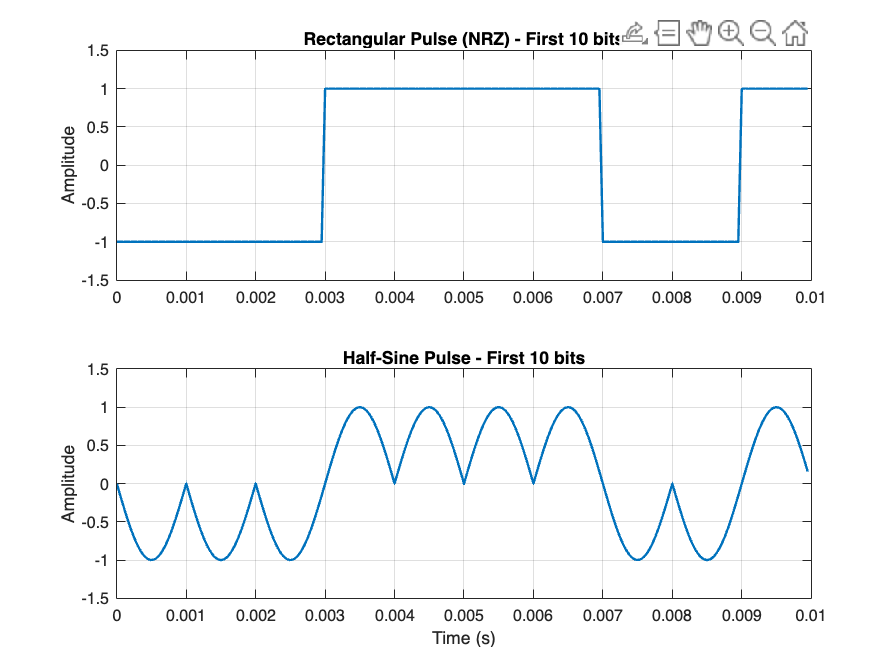

% 1. Define Pulses
pulse_rect = ones(1, L);                % Rectangular Pulse
pulse_sine = sin(pi * (0:L-1) / L);     % Half-Sine Pulse

% Calculate Pulse Energies (Important for N0 calculation)
E_rect = sum(pulse_rect.^2);
E_sine = sum(pulse_sine.^2);

% 2. Modulation (BPSK) -> Symbols: -1, +1
symbols = 2*bits - 1;

% Upsampling
symbols_upsampled = upsample(symbols, L);

% Pulse Shaping (Convolution)
tx_rect = filter(pulse_rect, 1, symbols_upsampled); % Rectangular Signal
tx_sine = filter(pulse_sine, 1, symbols_upsampled); % Half-Sine Signal

% 1.1 Waveform Visualization (First 10 bits)
t_plot = (0 : 10*L - 1) * Ts;
figure('Name', 'Sec 1: Time Domain Waveforms');

subplot(2,1,1);
plot(t_plot, tx_rect(1:10*L), 'LineWidth', 1.5); grid on;
title('Rectangular Pulse (NRZ) - First 10 bits'); ylabel('Amplitude');
ylim([-1.5 1.5]);

subplot(2,1,2);
plot(t_plot, tx_sine(1:10*L), 'LineWidth', 1.5); grid on;
title('Half-Sine Pulse - First 10 bits'); xlabel('Time (s)'); ylabel('Amplitude');
ylim([-1.5 1.5]);

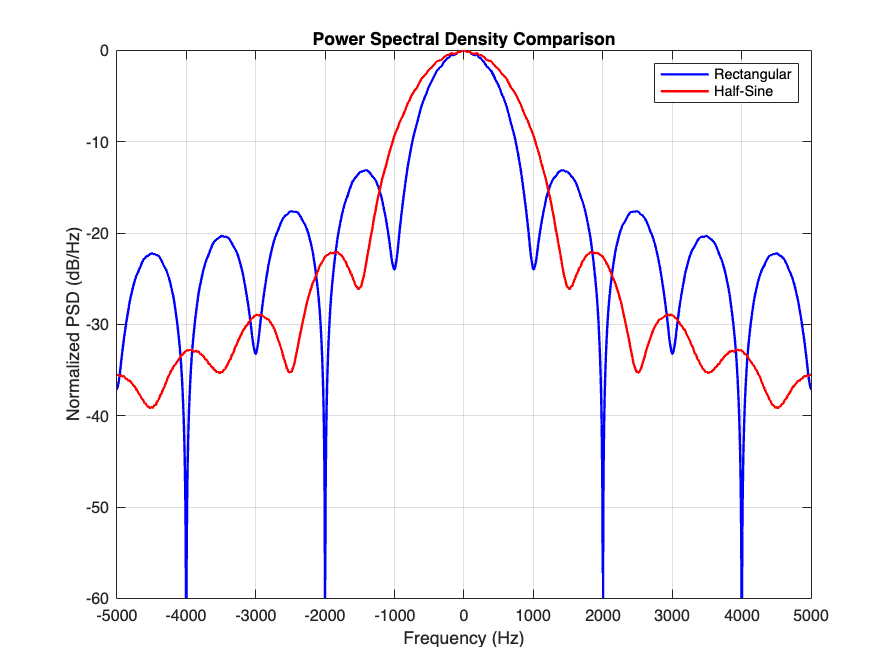

% 1.2 & 1.3 Spectrum Estimation
nfft = 4096; 
window_len = 500; 

[pxx_rect, f] = pwelch(tx_rect, rectwin(window_len), [], nfft, fs, 'centered');
[pxx_sine, ~] = pwelch(tx_sine, rectwin(window_len), [], nfft, fs, 'centered');

figure('Name', 'Sec 1: PSD Estimation');
plot(f, 10*log10(pxx_rect/max(pxx_rect)), 'b', 'LineWidth', 1.5); hold on;
plot(f, 10*log10(pxx_sine/max(pxx_sine)), 'r', 'LineWidth', 1.5);
grid on; legend('Rectangular', 'Half-Sine');
xlabel('Frequency (Hz)'); ylabel('Normalized PSD (dB/Hz)');
title('Power Spectral Density Comparison');
xlim([-5*Rb 5*Rb]); ylim([-60 0]);

## 2: Discrete-Time AWGN Modeling

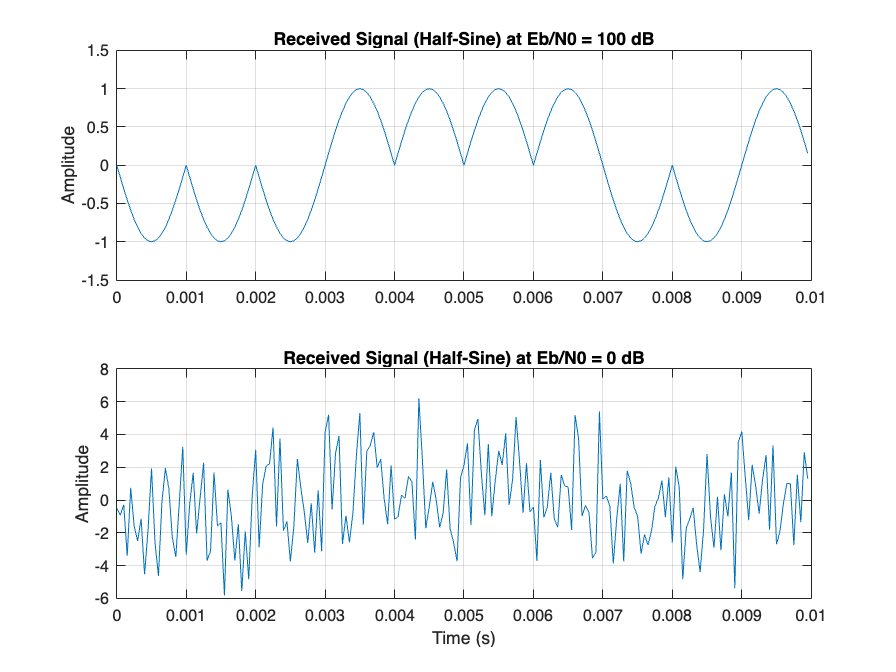

% 2.2 Noise Sensitivity Check
EbN0_test = [100, 0]; % dB values
figure('Name', 'Sec 2: Noise Sensitivity');

for i = 1:2
    snr_lin = 10^(EbN0_test(i)/10);
    noise_sigma = sqrt(E_sine / (2 * snr_lin));
    noise = noise_sigma * randn(size(tx_sine));
    rx_signal = tx_sine + noise;
    
    subplot(2,1,i);
    plot(t_plot, rx_signal(1:10*L)); grid on;
    title(['Received Signal (Half-Sine) at Eb/N0 = ' num2str(EbN0_test(i)) ' dB']);
    ylabel('Amplitude');
end
xlabel('Time (s)');

## 3: Matched Filter & SQNR Analysis

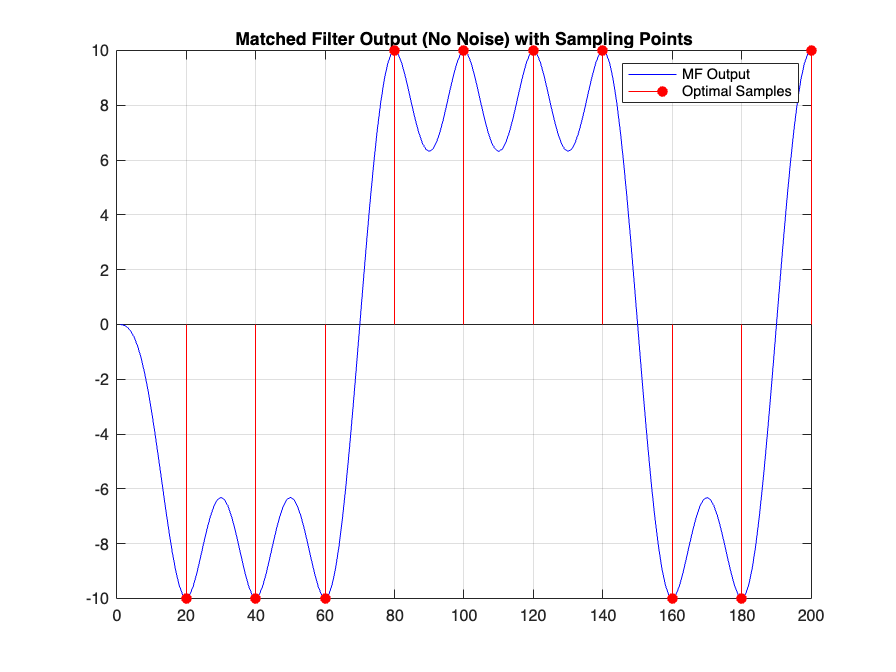

% 3.1 MF Implementation (for Half-Sine)
h_mf = fliplr(pulse_sine);
mf_output_pure = filter(h_mf, 1, tx_sine);

figure('Name', 'Sec 3: MF Output');
plot(mf_output_pure(1:10*L), 'b'); grid on; hold on;
stem(L:L:10*L, mf_output_pure(L:L:10*L), 'r', 'filled');
title('Matched Filter Output (No Noise) with Sampling Points');
legend('MF Output', 'Optimal Samples');

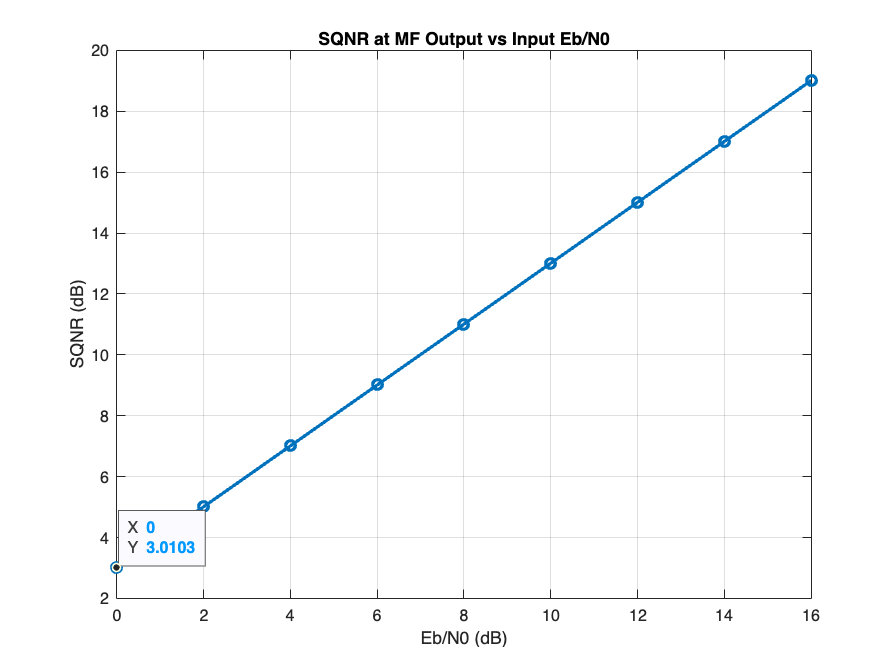

% 3.2 SQNR Curve Calculation
EbN0_vec = 0:2:16;
SQNR_dB = zeros(size(EbN0_vec));

Signal_Power_Peak = (E_sine)^2; 

for i = 1:length(EbN0_vec)
    snr_lin = 10^(EbN0_vec(i)/10);
    sigma_n_sq = E_sine / (2 * snr_lin);
    Noise_Power_Output = sigma_n_sq * E_sine;
    SQNR_linear = Signal_Power_Peak / Noise_Power_Output;
    SQNR_dB(i) = 10*log10(SQNR_linear);
end

figure('Name', 'Sec 3: SQNR vs Eb/N0');
plot(EbN0_vec, SQNR_dB, '-o', 'LineWidth', 2); grid on;
xlabel('Eb/N0 (dB)'); ylabel('SQNR (dB)');
title('SQNR at MF Output vs Input Eb/N0');

% Calculate and Display SQNR Slope 
p = polyfit(EbN0_vec, SQNR_dB, 1); % Linear regression
sqnr_slope = p(1); % The slope (m)
fprintf('   SQNR Slope: %.4f (Expected approx 1.0)\n', sqnr_slope);


>>> Section 3 Results:


   SQNR Slope: 1.0000 (Expected approx 1.0)


## 4: BER Comparison (BPSK, QPSK, 16-QAM)

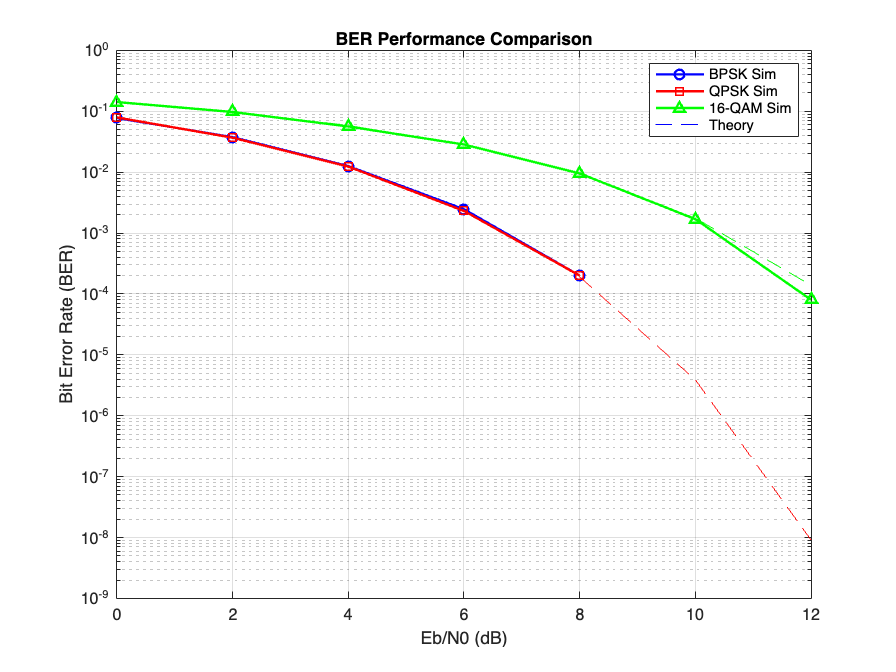

EbN0_dB_ber = 0:2:12; 
ber_bpsk = zeros(size(EbN0_dB_ber));
ber_qpsk = zeros(size(EbN0_dB_ber));
ber_16qam = zeros(size(EbN0_dB_ber));

% Theoretical BER
theo_bpsk = berawgn(EbN0_dB_ber, 'psk', 2, 'nondiff');
theo_qpsk = berawgn(EbN0_dB_ber, 'psk', 4, 'nondiff');
theo_16qam = berawgn(EbN0_dB_ber, 'qam', 16, 'nondiff');

for k = 1:length(EbN0_dB_ber)
    snr_db = EbN0_dB_ber(k);
    
    % BPSK Simulation (Updated to use pskmod/complex)
    % We use the original 'bits' generated at the start
    % 0 -> 1+0j, 1 -> -1+0j (Standard BPSK)
    mod_bpsk = pskmod(bits, 2, 0, 'gray'); 
    
    % AWGN Channel
    % For BPSK: SNR_dB = Eb/N0_dB (Since 1 bit per symbol)
    rx_bpsk = awgn(mod_bpsk, snr_db, 'measured');
    
    % Demodulation
    demod_bpsk = pskdemod(rx_bpsk, 2, 0, 'gray');
    
    % Error Counting
    [~, ber_bpsk(k)] = biterr(bits, demod_bpsk);
    
    
    % QPSK Simulation
    M = 4; k_bits = 2;
    data_qpsk = randi([0 M-1], 1, N_bits/2);
    mod_qpsk = pskmod(data_qpsk, M, pi/4, 'gray');
    % SNR per symbol = Eb/N0 + 10log10(k_bits)
    rx_qpsk = awgn(mod_qpsk, snr_db + 10*log10(k_bits), 'measured');
    demod_qpsk = pskdemod(rx_qpsk, M, pi/4, 'gray');
    [~, ber_qpsk(k)] = biterr(data_qpsk, demod_qpsk);
    
    % 16-QAM Simulation
    M = 16; k_bits = 4;
    data_16qam = randi([0 M-1], 1, N_bits/4);
    mod_16qam = qammod(data_16qam, M, 'gray');
    rx_16qam = awgn(mod_16qam, snr_db + 10*log10(k_bits), 'measured');
    demod_16qam = qamdemod(rx_16qam, M, 'gray');
    [~, ber_16qam(k)] = biterr(data_16qam, demod_16qam);
end

% Plotting
figure('Name', 'Sec 4: BER Comparison');
semilogy(EbN0_dB_ber, ber_bpsk, 'b-o', 'LineWidth', 1.5); hold on;
semilogy(EbN0_dB_ber, ber_qpsk, 'r-s', 'LineWidth', 1.5);
semilogy(EbN0_dB_ber, ber_16qam, 'g-^', 'LineWidth', 1.5);
semilogy(EbN0_dB_ber, theo_bpsk, 'b--');
semilogy(EbN0_dB_ber, theo_qpsk, 'r--');
semilogy(EbN0_dB_ber, theo_16qam, 'g--');
grid on;
legend('BPSK Sim', 'QPSK Sim', '16-QAM Sim', 'Theory');
xlabel('Eb/N0 (dB)'); ylabel('Bit Error Rate (BER)');
title('BER Performance Comparison');

% Calculations: MSE, Required Eb/N0, Penalty 

% 1. Calculate MSE (Simulated vs Theory)
mse_bpsk = mean((ber_bpsk - theo_bpsk).^2);
mse_qpsk = mean((ber_qpsk - theo_qpsk).^2);
mse_16qam = mean((ber_16qam - theo_16qam).^2);

% 2. Calculate Required Eb/N0 for BER = 10^-3
target_ber = 1e-3;

% Filter valid indices (BER > 0) for log interpolation
valid_idx_bpsk = ber_bpsk > 0;
req_bpsk = interp1(log10(ber_bpsk(valid_idx_bpsk)), EbN0_dB_ber(valid_idx_bpsk), log10(target_ber), 'linear', 'extrap');

valid_idx_16qam = ber_16qam > 0;
req_16qam = interp1(log10(ber_16qam(valid_idx_16qam)), EbN0_dB_ber(valid_idx_16qam), log10(target_ber), 'linear', 'extrap');

% 3. Power Penalty
power_penalty = req_16qam - req_bpsk;



>>> Section 4 Results:


fprintf('   BPSK MSE:   %.2e\n', mse_bpsk);

   BPSK MSE:   1.26e-07


fprintf('   QPSK MSE:   %.2e\n', mse_qpsk);

   QPSK MSE:   1.22e-07


fprintf('   16-QAM MSE: %.2e\n', mse_16qam);

   16-QAM MSE: 9.20e-07


fprintf('\n');
fprintf('   Required Eb/N0 (BER=10^-3) for BPSK:   %.2f dB\n', req_bpsk);

   Required Eb/N0 (BER=10^-3) for BPSK:   6.72 dB


fprintf('   Required Eb/N0 (BER=10^-3) for 16-QAM: %.2f dB\n', req_16qam);

   Required Eb/N0 (BER=10^-3) for 16-QAM: 10.34 dB


fprintf('   Power Penalty (16-QAM vs BPSK):        %.2f dB\n', power_penalty);

   Power Penalty (16-QAM vs BPSK):        3.63 dB


--------------------------------------------------


## Section 5: Non-Ideal Effects & Eye Diagram

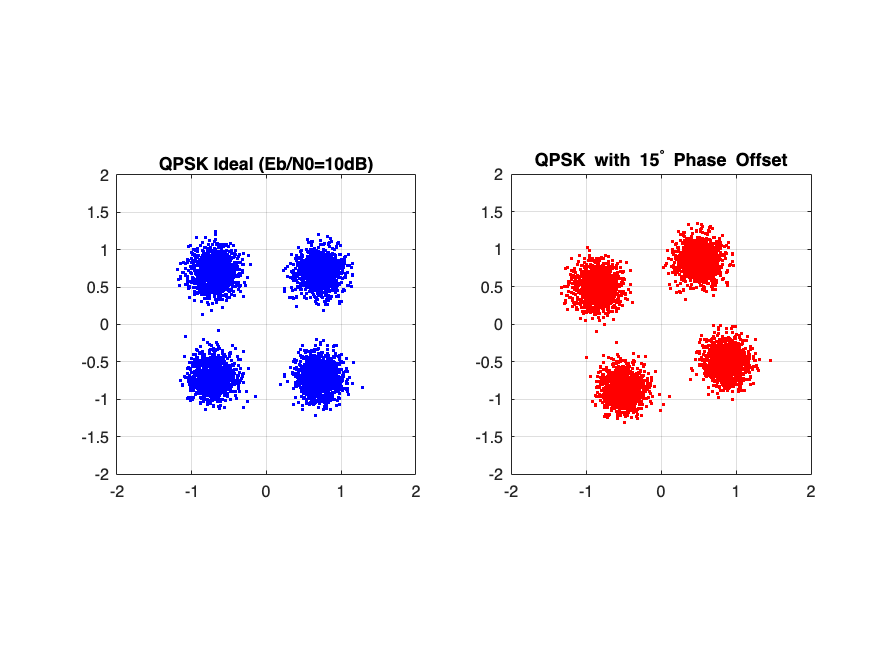

% 5.1 & 5.2 Phase/Freq Offset
M = 4; k_bits = 2; EbN0_target = 10; num_syms = 5000;
data_qpsk = randi([0 M-1], 1, num_syms);
mod_qpsk = pskmod(data_qpsk, M, pi/4, 'gray');
rx_qpsk_ideal = awgn(mod_qpsk, EbN0_target + 10*log10(k_bits), 'measured');

% Phase Offset
phase_val = 15 * (pi/180);
rx_qpsk_phase = rx_qpsk_ideal * exp(1j * phase_val);

figure('Name', 'Sec 5: Phase Offset');
subplot(1,2,1); plot(real(rx_qpsk_ideal), imag(rx_qpsk_ideal), '.b'); grid on; axis equal;
title(['QPSK Ideal (Eb/N0=' num2str(EbN0_target) 'dB)']); xlim([-2 2]); ylim([-2 2]);
subplot(1,2,2); plot(real(rx_qpsk_phase), imag(rx_qpsk_phase), '.r'); grid on; axis equal;
title('QPSK with 15^\circ Phase Offset'); xlim([-2 2]); ylim([-2 2]);

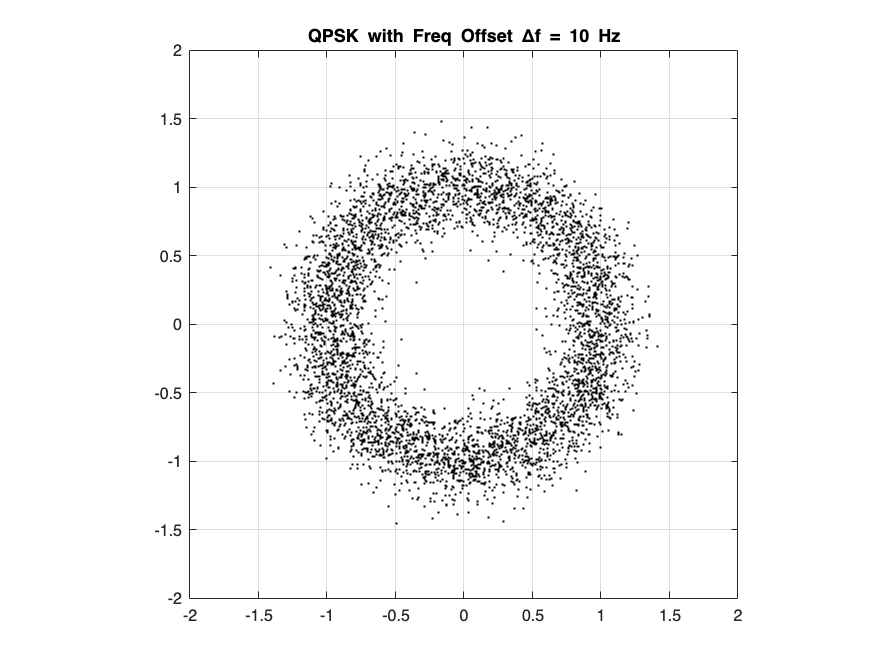

--- Section 5.3: Eye Diagram ---


% Freq Offset
delta_f = 0.01 * Rb;
t_sym = (0:length(mod_qpsk)-1) * (1/Rb); 
freq_offset_term = exp(1j * 2 * pi * delta_f * t_sym);
rx_qpsk_freq = rx_qpsk_ideal .* freq_offset_term;

figure('Name', 'Sec 5: Frequency Offset');
plot(real(rx_qpsk_freq), imag(rx_qpsk_freq), '.k', 'MarkerSize', 4); grid on; axis equal;
title(['QPSK with Freq Offset \Deltaf = ' num2str(delta_f) ' Hz']); xlim([-2 2]); ylim([-2 2]);

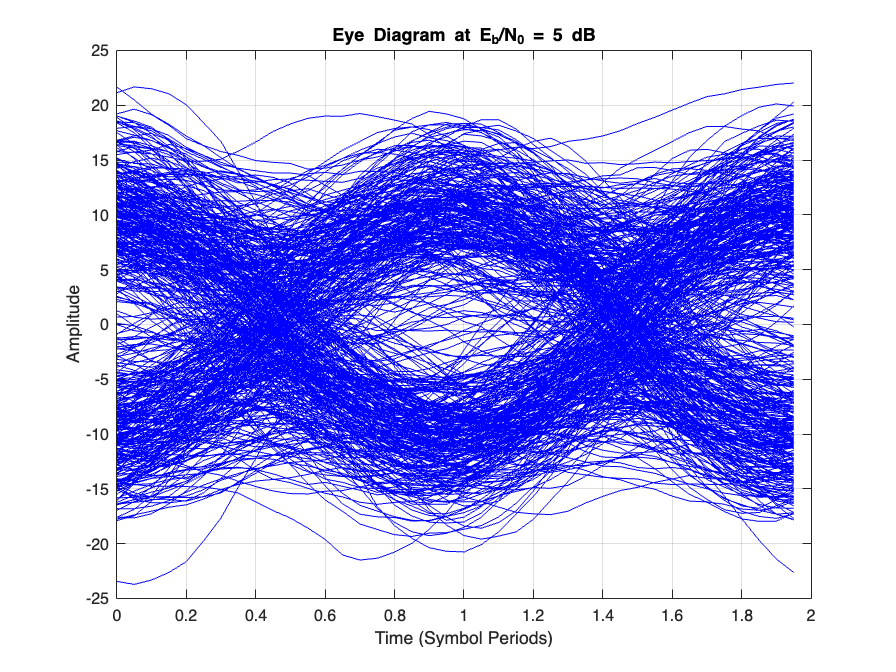

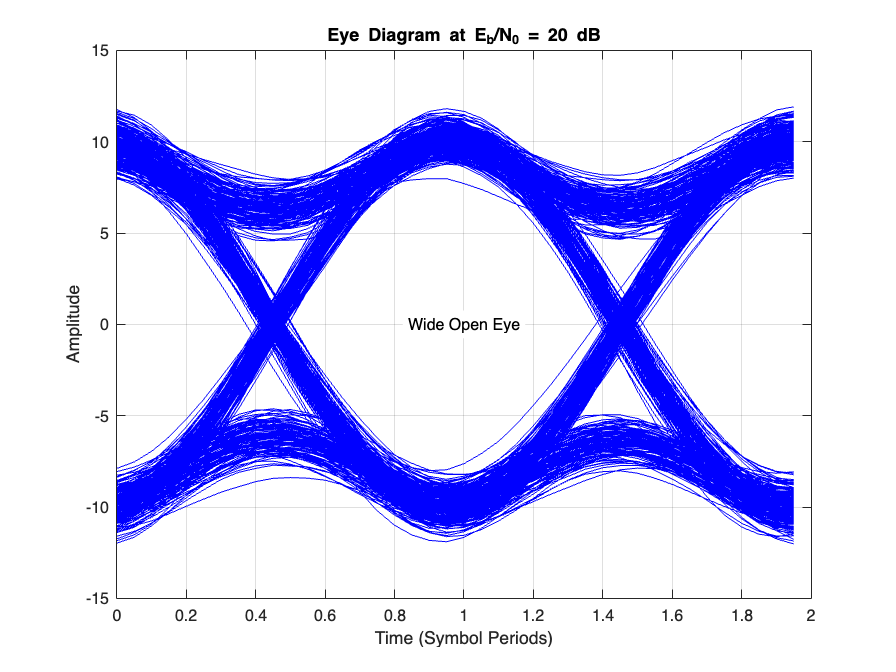

% Parameters for Eye Diagram
snr_eye_vec = [5, 20]; % dB values
n_eye_bits = 1000;     % Increased bits for better density

% Generate bits and symbols
bits_eye = randi([0 1], 1, n_eye_bits);
sym_eye = 2*bits_eye - 1;
tx_eye_up = upsample(sym_eye, L);
tx_eye = filter(pulse_sine, 1, tx_eye_up); 
h_mf = fliplr(pulse_sine);

% Loop for each SNR
for i = 1:length(snr_eye_vec)
    curr_snr = snr_eye_vec(i);
    snr_lin = 10^(curr_snr/10);
    
    % Noise and Filtering
    sigma_eye = sqrt(E_sine / (2 * snr_lin));
    noise_eye = sigma_eye * randn(size(tx_eye));
    rx_eye = tx_eye + noise_eye;
    mf_out_eye = filter(h_mf, 1, rx_eye);
    
    % Remove transients (Filter delay)
    mf_out_stable = mf_out_eye(L+1:end);
    
    % MANUAL EYE DIAGRAM CONSTRUCTION FOR MLX
    % Logic: Reshape the signal so each column is 2 symbol periods (2*L)
    samples_per_trace = 2 * L;
    
    % Ensure data length is integer multiple of trace length
    num_traces = floor(length(mf_out_stable) / samples_per_trace);
    data_to_plot = mf_out_stable(1 : num_traces * samples_per_trace);
    
    % Reshape: Each column becomes one trace
    eye_matrix = reshape(data_to_plot, samples_per_trace, num_traces);
    
    % Time vector for X-axis
    t_eye = (0 : samples_per_trace - 1) / L; % Normalized time (0 to 2 Tb)
    
    % Plotting using standard 'plot' command (forces inline display)
    figure('Name', ['Eye Diagram ' num2str(curr_snr) ' dB']);
    plot(t_eye, real(eye_matrix), 'b'); % 'b' makes all lines blue
    grid on;
    title(['Eye Diagram at E_b/N_0 = ' num2str(curr_snr) ' dB']);
    xlabel('Time (Symbol Periods)');
    ylabel('Amplitude');
    xlim([0 2]); % Show exactly 2 symbol intervals
    
    % Optional: Add text explanation
    if curr_snr == 20
        text(1, 0, 'Wide Open Eye', 'HorizontalAlignment', 'center', 'BackgroundColor', 'w');
    end
end